# Template of Manipulator Short project: Skull tumor surgery

Authors: 

Team:  

Shared Link with the teacher: 

I spect: 1) Pdf file, 2) Videos demostrating your successful task and your mlx file.

Notes. For better undestanding you can split the videos in the meaninful task.

Remember use the options of serial/link plot: 

'workspace' for centering in the surgery task

'zoom' ...  nice puma ratio aspect

'trail'  .. to see the trajectory

etc..

See all at:

>> help SerialLink/plot

## The Robotic environment (10%)

Think that later on the enviroment will move to any place in a Univers Reference Frame {U}

Use: 'c = uisetcolor' to chose your prefered colors

### Operating table.

 It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Define: Vertices and Faces and use  'patch'  functions to model it. See help patch to find and example.

Think that later on the enviroment will move to any place in a Univers Reference Frame {U}

**Expected results**

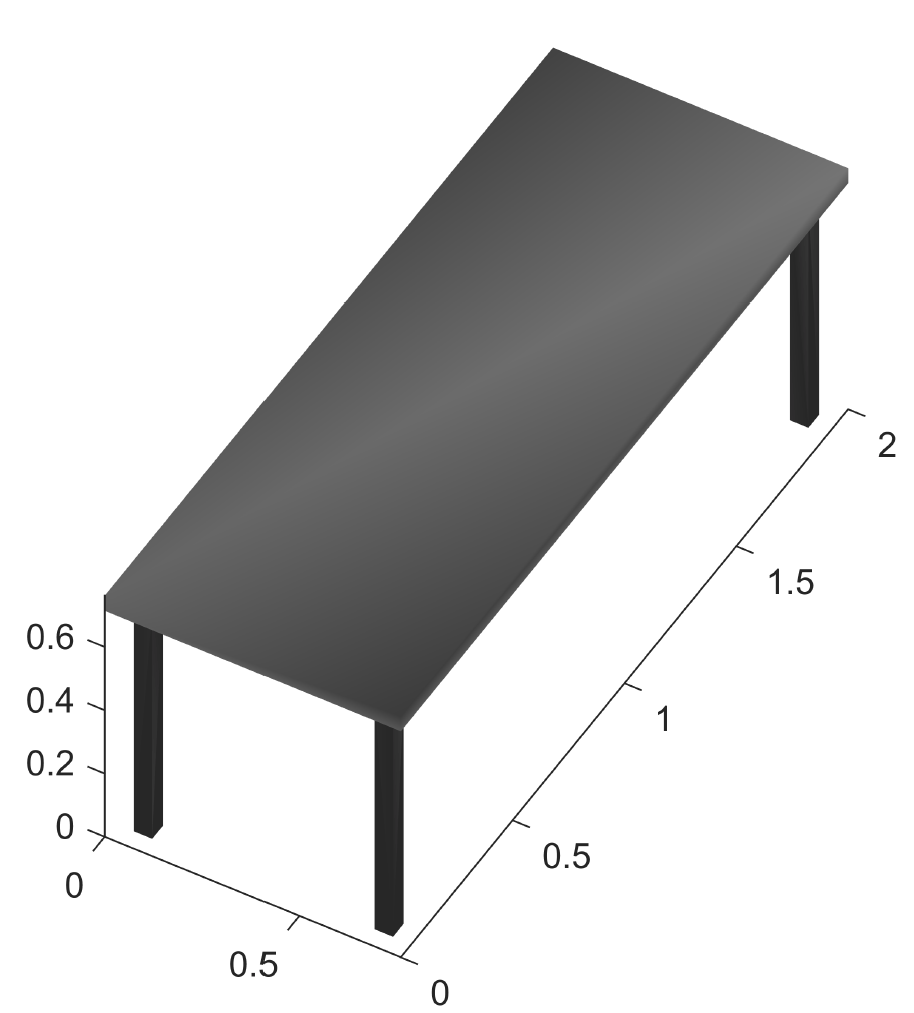

%% put your code Here

### 3D model of a human body 

Situate the human model on the operating table. 

**Expected results**

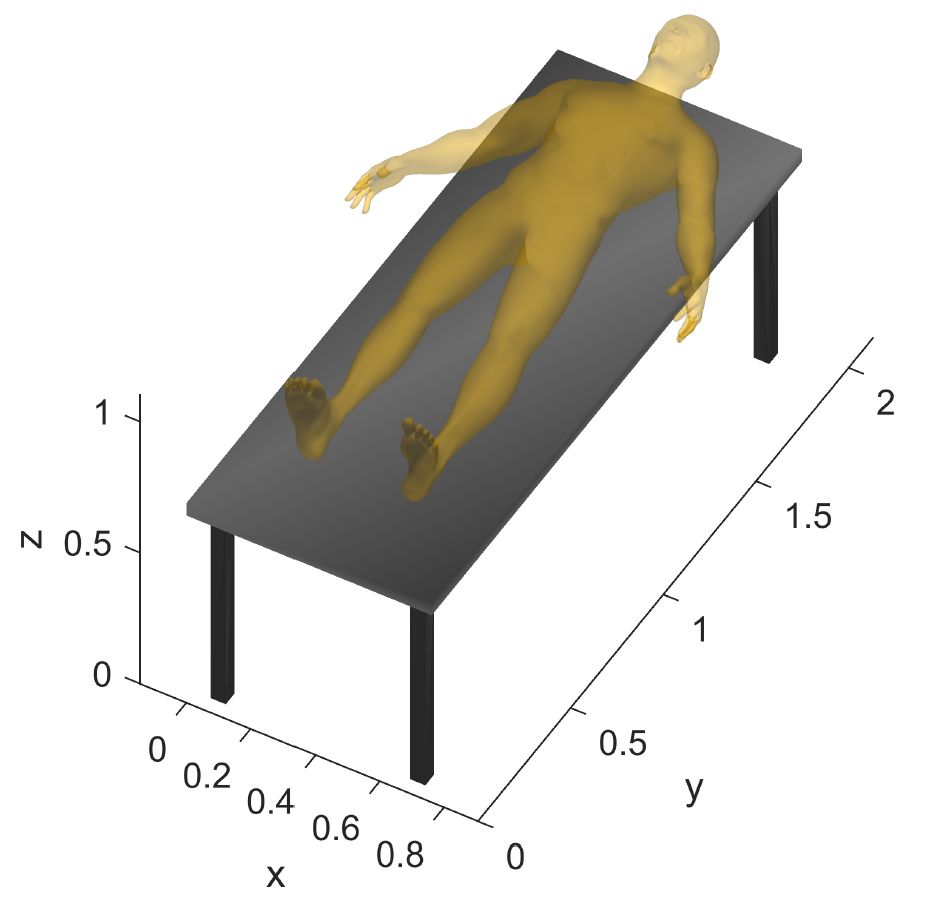

%% put your code Here

### Fiducials

The Radiology Department before to take a Computer Tomography (CT) of the brain, fix three fiducials in the head of the patient for registering purpose,  visit: [https://en.wikipedia.org/wiki/Fiducial](https://en.wikipedia.org/wiki/Fiducial)

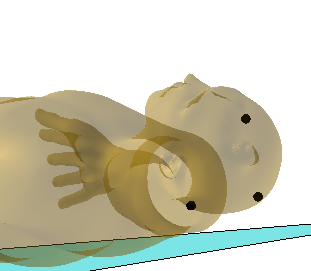

### Dicom image vs Image Reference frame {I}

Get familiar with Dicom Images, Visit: https://www.imaios.com/en/Imaios-Dicom-Viewer#!

Use a container Box of the skull  to infer the Image Reference Frame {I}

See:  6_Plot_Box_Cone.mlx and 7_Help_Image_RF_Containig_Box.fig to inspire yourselt 

**Expected results**

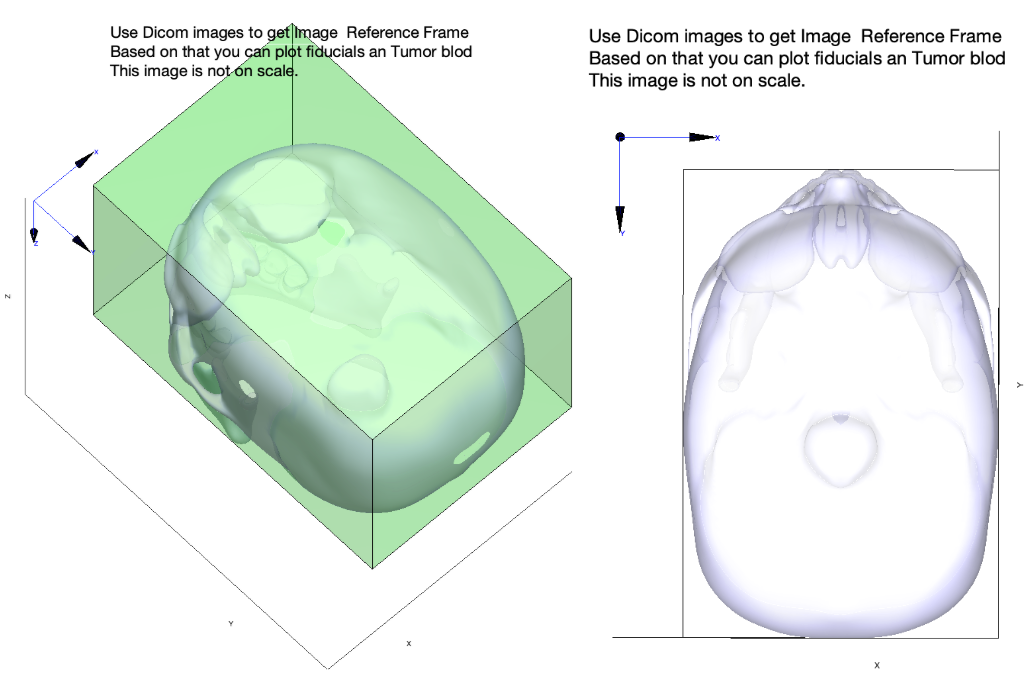

%% put your code Here

### Fiducials wrt {I}

Use the Dicom images to place the fiducial relative to Image Reference Frame {I}.

See: 5_Skull_pose_estimation.mlx and use the skull to make the exercise.

**Expected results**

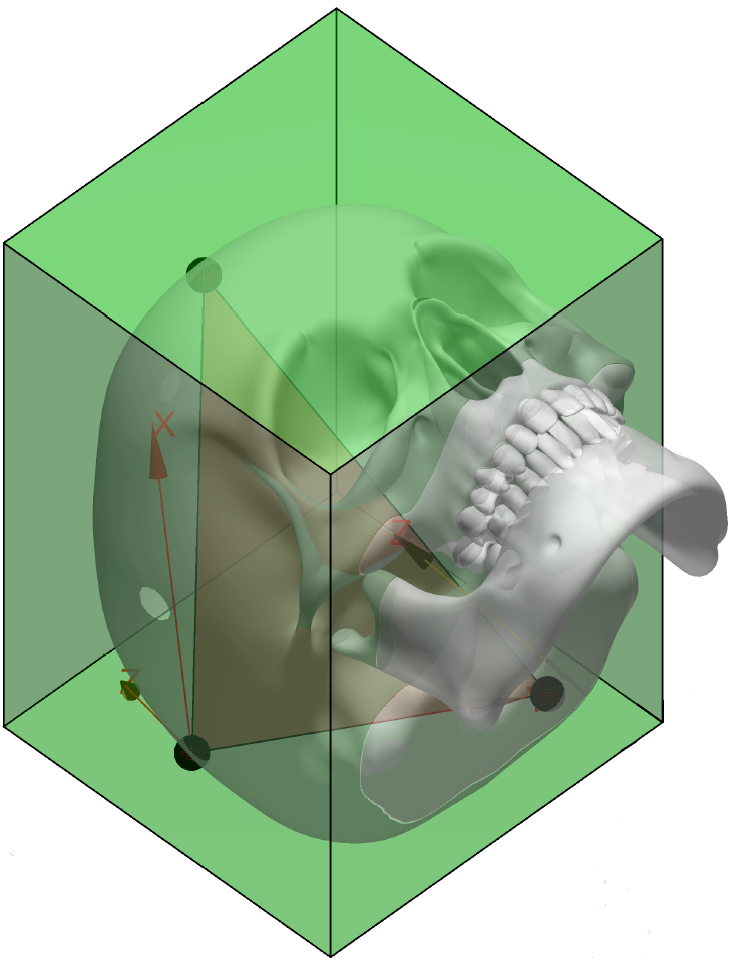

%% put your code Here

### Tumor points wrt {I}

Use the Dicom images to get the points of the outer perimeter of the tumor relative to Image Reference Frame {I}.

You can simplify the tumor information by defining the center of mass and estimate an equivalent diameter.

**Expected results**

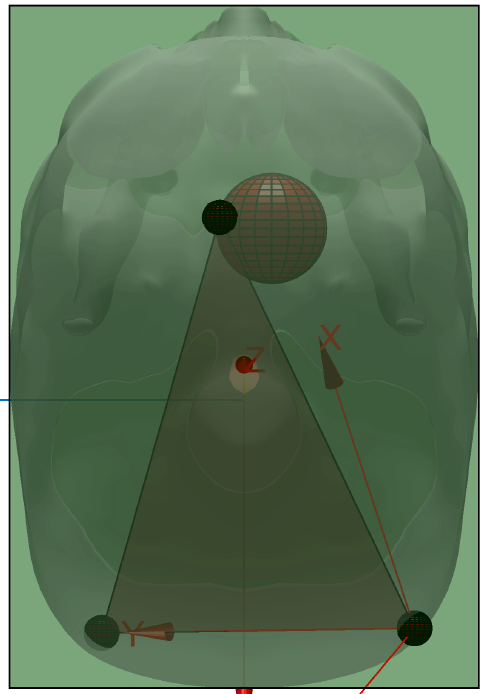

%% put your code Here

### Fiducials and Tumor wrt Human Reference Frame

Place fiducial and tumor in the head of the human. You will have to re-do the containing box secction.

**Expected results**

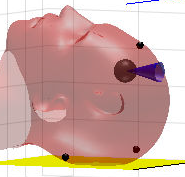

## *First approach (10%)  *

*Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

### Robot manipulator

Consider  the best position of manipulator to be nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560. Use p560.teach to play.

Use: p560.base & p560.tool to locate the Puma and add the tools.

**Expected results**

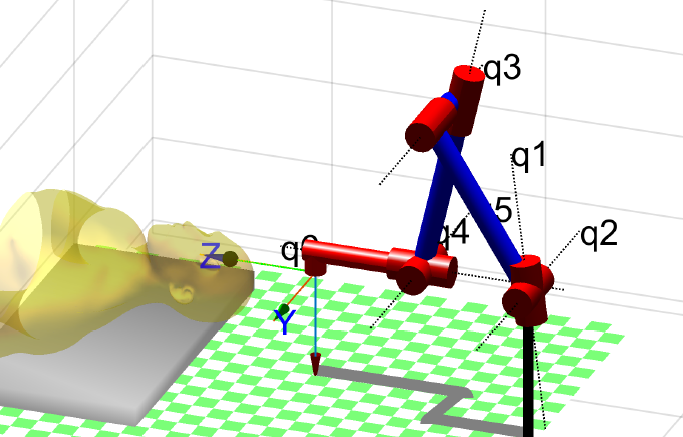

%% put your code Here

### Reference Frames

Display all necessary reference frame. Use best scale to see it.

- {U} Univers [0 0 0]

- {R} Robot

- {I} Image

- {Tb} Table_body

- {Tt} Table tool

- {EE} End Efector

- others

- ...

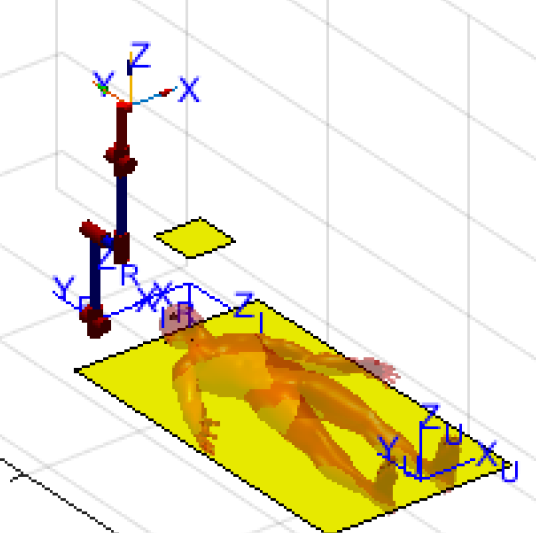

%% put your code Here

### Transformations

Enumerate the transformation you will need.

%% put your code Here

### Tumor points in Robot Frame.

Remember the Transform compound exercise

%% put your code Here


## *Second approach: ( 25%)*

Modify your code  to repeat the exercise if you can infer the Fiducial wrt Robot Rosa knowing fiducial wrt {U} (open: Robot_Rosa_fiducials.mat) and placing the Robot Rosa accordinly as happend in the Rosa video: https://youtu.be/kPzDq9Tb0uE.

## Surgery (55%)

### Biospy

Prepare a script that perform a biopsy. Zoom in the scene and record a video with the best view.

Take into account:

- Use a tool that has the following Transformation: transl(0.05 0 0.25)

- Use 'trail' option of plot to visualize the trajectory.

- The speed of biopsy function that you design ought to be a parameter to satisfy the surgeons.

Answer these questions:

- Display in a figure the displacement, velocity and aceleration of the tool i End Efector Reference frame.

- How much enter the tool in the patient brain.

- What are the speed of the tool in Wordl Reference Frame.

%% put your code Here

### Trepanation

Prepare a script that perform trepanation. Define a normal unitary vector with restpect to the skull and perform the trepanation such that the Z unitary vector of the End Effector (Trepanation

Prepare a script that perform trepanation. Define a normal unitary vector with restpect to the skull and perform the trepanation such that the Z unitary vector of the End Effector (Z_u_s), that is the tool form 45º along all the trajectoy with respect (Z_u_s). The hole must be litle bit less than the Tumor diameter. 

Zoom in the scene and record a video with the best view.

Take into account:

Use a tool that has the following Transformation: transl(0 0 0.2)

Use 'trail' option of plot to visualize the trajectory.

Place a 45º cone on top of the trepanation to better understand. 

See: 6_Plot_Box_Cone_fiducials.mlx. You will have to scale it. Play with transparency.

Answer these questions:

Display in a figure the lineal displacement, velocity and aceleration of the tool in End Efector Reference frame.

Display in a figure the manipulabitlity of the trepanation function either for translation and rotation.

Find an alternate robot location for improving your manipulabitity.), that is the tool form 45º along all the trajectoy. The hole must be litle bit less than tha Tumor diameter. 

Zoom in the scene and record a video with the best view.

Take into account:

- Use a tool that has the following Transformation: transl(0 0 0.2)

- Use 'trail' option of plot to visualize the trajectory.

- Place a 45º cone on top of the trepanation to better understand. 

- See: 6_Plot_Box_Cone_fiducials.mlx. You will have to scale it. Play with transparency.

Answer these questions:

- Display in a figure the lineal displacement, velocity and aceleration of the tool in End Efector Reference frame.

- Display in a figure the manipulabitlity of the trepanation function either for translation and rotation.

- Find an alternate robot location for improving your manipulabitity.

%% put your code Here

### Tumor burning

Prepare a script that perform tumor burning with the laser.  Zoom in the scene and record a video with the best view.

You ought to think in an algorithm, that in order, fill up the tumor's  equivalent sphere with small burning spheres of 4mm diameter.

Use a tool that has the following Transformation: transl(0 0 0.2)

Answer these questions:

- Display in a figure the lineal displacement, velocity and aceleration of the tool in End Efector Reference frame.

- How long it takes your burning function to burn the tumor

%% put your code Here